
%s=tf('s');
%G=(1/(s^4+12*s^3+64*s^2+128*s)) %funcion de transferencia
%Tk=feedback(G,1);
%subplot(131);
%step(Tk);
%subplot(132);
%lsim(Tk,0:.1:10,0:.1:10)
%subplot(133);
%lsim(Tk/s,0:.1:10,0:.1:10)


%punto4
%AQui mostramos error
clear all;
clc;
s=tf('s');
%G=C
%G=(1/(s^5+1*s^4+85*s^3+225*s^2+274*s+120))
G=zpk([],[-1 -4 0 ],20)

G =
 
       20
  -------------
  s (s+1) (s+4)
 
Continuous-time zero/pole/gain model.



%G=(60*(s+3)*(s+4)*(s+8))/((s^2)*(s+6)*(s+17))
E=zpk(G)

E =
 
       20
  -------------
  s (s+1) (s+4)
 
Continuous-time zero/pole/gain model.



kp=dcgain(G)

kp = Inf

kv=dcgain(G*s)

kv = 5

ka=dcgain(G*s^2)

ka = 0

eep=1/(1+kp)

eep = 0

eev=1/kv

eev = 0.2000

eea=1/ka

eea = Inf

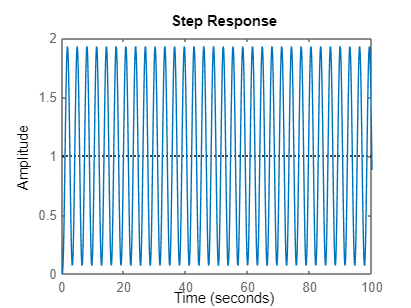

Tk=feedback(G,1);
step(Tk)

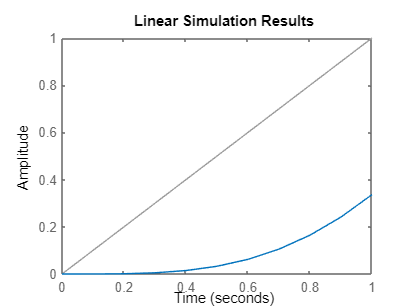

t=0:0.1:1;
lsim(Tk,t,t);

x=t.^2

x =          0    0.0100    0.0400    0.0900    0.1600    0.2500    0.3600    0.4900    0.6400    0.8100    1.0000


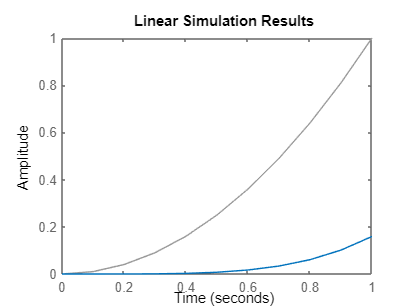

lsim(Tk,x,t);

%otra forma de hacerlo
syms s t

% Define la función de transferencia H(s)
Hs = ((3*s + 1) * exp(-s)) / ((s+1) * (2*s+1) * (10*s+1));

% Calcula la transformada inversa de Laplace
yt = ilaplace(Hs, s, t);

% Calcula la constante de posición (Kp)
Kp = limit(yt, t, Inf);

% Calcula la constante de velocidad (Kv)
Kv = limit(diff(yt, t), t, Inf);

% Calcula la constante de aceleración (Ka)
Ka = limit(diff(yt, t, 2), t, Inf);

%punto2
%implementar accion basica
G4=zpk([],[-10 -4  ],140)

G4 =
 
      140
  ------------
  (s+10) (s+4)
 
Continuous-time zero/pole/gain model.



%implementacion de un proporcional
kp=dcgain(G4*7);%implementamos una ganacia de 7
kv=dcgain(G4*s);
eep=1/(1+kp)

eep = 0.0392

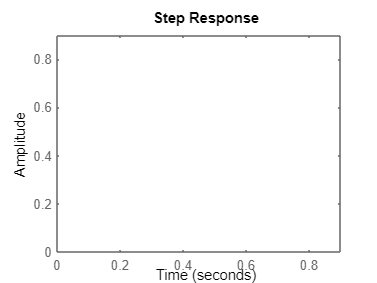

Tk1=feedback(G4,1);
step(Tk1)

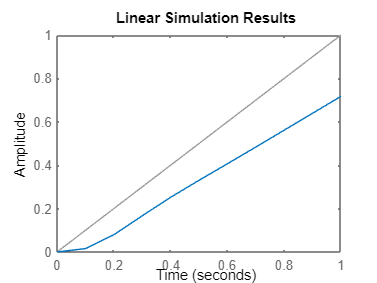

lsim(Tk1,t,t);

x=t.^2;

x =          0    0.0100    0.0400    0.0900    0.1600    0.2500    0.3600    0.4900    0.6400    0.8100    1.0000


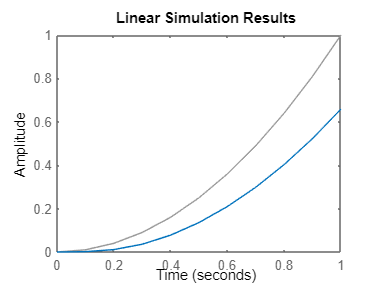

lsim(Tk1,x,t);

%tomar funcion de transferencia
s = tf('s');
                %insertar nombre de archivo de simulink
[num,den]=linmod('Errores_de_posicion')

num = 	1.0e+07 *

         0         0   -2.5000         0         0


den = 	1.0e+07 *

    0.0000    0.0005    2.5000         0         0


Gt=tf(num,den)

Gt =
 
          -2.5e07 s^2
  ---------------------------
  s^4 + 5000 s^3 + 2.5e07 s^2
 
Continuous-time transfer function.



minreal(Gt)

ans =
 
         -2.5e07
  ---------------------
  s^2 + 5000 s + 2.5e07
 
Continuous-time transfer function.



E=zpk(Gt)

E =
 
         -2.5e07 s^2
  --------------------------
  s^2 (s^2 + 5000s + 2.5e07)
 
Continuous-time zero/pole/gain model.



kp=dcgain(Gt)

kp = -1.0000

kv=dcgain(Gt*s)

kv = 0

ka=dcgain(Gt*s^2)

ka = 0

eep=1/(1+kp)

eep = -4.5036e+15

eev=1/kv

eev = Inf

eea=1/ka

eea = Inf

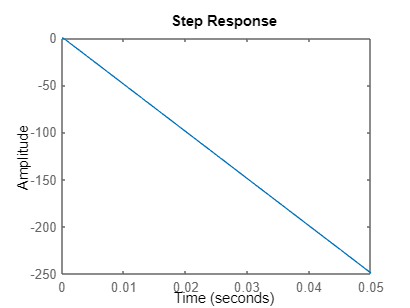

Tk=feedback(Gt,1);
step(Tk)

%PUNTO 6 ESTABILIDAD Y ERRORES DE POSICION
s = tf('s');
K=20;
GJ=(K/(s^5+1*s^4+85*s^3+225*s^2+274*s+120))%Funcion de transferencia

GJ =
 
                      1
  ------------------------------------------
  s^5 + s^4 + 85 s^3 + 225 s^2 + 274 s + 120
 
Continuous-time transfer function.



%GJ1=zpk(GJ)

GJ1 =
 
                             1
  --------------------------------------------------------
  (s+0.8177) (s^2 + 1.838s + 1.703) (s^2 - 1.656s + 86.19)
 
Continuous-time zero/pole/gain model.



pole(GJ)

ans =    0.8279 + 9.2470i
   0.8279 - 9.2470i
  -0.9191 + 0.9262i
  -0.9191 - 0.9262i
  -0.8177 + 0.0000i


%roots(GJ)

Error using InputOutputModel/subsref (line 43)
Use two or more subscripts to select or delete all elements, as in the "sys(:,:)" command.

Error in roots (line 30)
c = c(:).';

E=zpk(GJ)

kp=dcgain(GJ);
kv=dcgain(GJ*s);
ka=dcgain(GJ*s^2);
eep=1/(1+kp)
eev=1/kv
eea=1/ka

%Crear una funcion de transferencia
% Definir los ceros, polos y ganancia
zeros = [-3 1];   % Ceros en s = -1 y s = -2
poles = [-3, -4]

   % Polos en s = -3 y s = -4
ganancia = 1;       % Ganancia igual a 1

% Crear la función de transferencia ZPK
sys = zpk(zeros, poles, ganancia)
